# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá. SPAIN.**

# Topic 4 part 2: exercise 03 - Moments

## Questions 

## 1) General Moments

- Calculate the general moments up to the 1st order of the original image (`I`) and the translated image (`It`). Use the `general_moments` function (step 3).

- Are these moments invariant to translation?

## 2) Central Moments

- Calculate the central moments up to the 1st order of the original image (`I`), the translated image (`It`) and the rotated image (`Ir`). Use the central`_moments` function (step 4).

- Are these moments invariant to translation and rotation?

## 3) Hu Moments

- Calculate the Hu moments of the original image (`I`), the translated, scaled and rotated image (`Itsr`). Use the hu`_moments` function (step 5).

- Are these moments invariant to the translation scale and rotation?

- Load the image 'B.jpg' and compare the values of the Hu moments with those obtained for the image 'A.jpg', are they different?

Step 1) Read Image

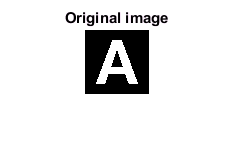

% Read original image.
I = imread('A.jpg');

if size(I,3) == 3
        I = rgb2gray(I); 
    end
I = imbinarize(I);
I = imcomplement(I);

imshow(I);
title('Original image');

Step 2) Translate, Resize and Rotate the Image

Translation

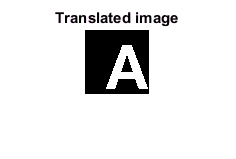

tx = 10; % x translation
ty = 5; % y translation
It = imtranslate(I,[tx, ty]); % Translated image

figure,
imshow(It)
title('Translated image');

Scaled

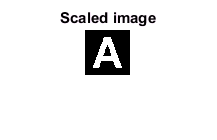

scale = 0.7; % scale factor.
Is = imresize(I, scale); % scaled image
figure,
imshow(Is)
title('Scaled image');

Rotation

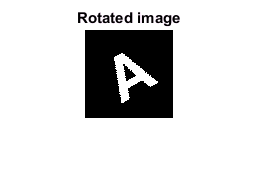

theta = 30; % the angle, theta.
Ir = imrotate(I,theta); % rotated image

figure,
imshow(Ir)
title('Rotated image');

Translate, Resize and Rotate

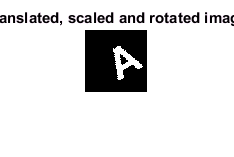

Its = imresize(It, scale); % Translated and scaled image
Itsr = imrotate(Its,theta);% Translated, scaled and rotated image
figure,
imshow(Itsr)
title('Translated, scaled and rotated image');

Step 3) general moments

general_moments(I,3)

ans =    1.0e+12 *

    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0014
    0.0000    0.0000    0.0014    0.0547
    0.0000    0.0015    0.0575    2.3475



general_moments(It,3)

ans =    1.0e+12 *

    0.0000    0.0000    0.0000    0.0001
    0.0000    0.0000    0.0001    0.0031
    0.0000    0.0001    0.0028    0.1369
    0.0001    0.0028    0.1307    6.4117


%%es variante




Step 4) central moments

central_moments(I,3)

ans =    1.0e+08 *

    0.0000   -0.0000    0.0008   -0.0001
   -0.0000    0.0000    0.0066   -0.0009
    0.0012    0.0000    0.1217   -0.0144
   -0.0038    0.0006    1.4800   -0.2021


central_moments(Ir,3)

ans =    1.0e+08 *

    0.0000    0.0000    0.0009    0.0070
   -0.0000    0.0001    0.0006    0.0632
    0.0011   -0.0056    0.0764   -0.2762
    0.0017    0.0079   -0.1547    6.2429



central_moments(It,3)

ans =    1.0e+08 *

    0.0000   -0.0000    0.0008   -0.0001
   -0.0000    0.0000    0.0066   -0.0009
    0.0012    0.0000    0.1217   -0.0144
   -0.0038    0.0006    1.4800   -0.2021


%%en It es invariante
%%en Ir es variante

Step 5) Hu moments

hu_moments(I)

ans =     0.2817    0.0022    0.0132    0.0002   -0.0000    0.0000   -0.0000


hu_moments(Itsr)

ans =     0.2826    0.0023    0.0133    0.0002   -0.0000    0.0000   -0.0000


## en A presenta variación

I = imread('B.jpg');
if size(I,3) == 3
        I = rgb2gray(I); 
    end
I = imbinarize(I);
I = imcomplement(I);
tx = 10; % x translation
ty = 5; % y translation
It = imtranslate(I,[tx, ty]); % Translated image
scale = 0.7; % scale factor.
Is = imresize(I, scale); % scaled image
theta = 30; % the angle, theta.
Ir = imrotate(I,theta); % rotated image
Its = imresize(It, scale); % Translated and scaled image
Itsr = imrotate(Its,theta);% Translated, scaled and rotated image
hu_moments(I)

ans =     0.2193    0.0031    0.0001    0.0000    0.0000   -0.0000    0.0000


hu_moments(Itsr)

ans =     0.2183    0.0031    0.0000    0.0000   -0.0000   -0.0000   -0.0000


%% en B presenta más variación